# **Script comparing performance of the old style (@coneMosaicHex-based) to the new style (@cMosaic-based) cone mosaic**

*Copyright: Nicolas P. Cottaris,  ISETBio Team, 2022*

# **Step 1.** Generate treeshrew optics

theOI = oiTreeShrewCreate('pupilDiameterMM', 2.0);
micronsPerDegree = theOI.optics.micronsPerDegree;

# **Step 2.** Generate new- and old-style tree shrew cone mosaics

% Scene will be 8 degrees wide
sceneFOVdegs = 8.0;

% Mosaics will be 5x5 degrees
mosaicFOVdegs = [5 5];

% Integration time
integrationTimeSeconds = 500/1000;

% Old way of generating a @coneMosaicHex for the threeshrew
theOldStyleTreeShrewConeMosaic = coneMosaicTreeShrewCreate(...
    micronsPerDegree, ...
    'fovDegs', mosaicFOVdegs , ...
    'integrationTime', integrationTimeSeconds);


Resampling grid. Please wait ... Done !
Will not change the S-cone density.
Scones before making an S-cone free central patch: 2087
Scones after making an S-cone free central patch: 2087 (added Lcones:0, added Mcones:0)
Scones after pass 1: 1236 (added Lcones:1112, added Mcones:0)
Scones after pass 2: 735 (added Lcones:665, added Mcones:0)
Scones after pass 3: 436 (added Lcones:387, added Mcones:0)
Scones after pass 4: 269 (added Lcones:209, added Mcones:0)
Scones after pass 5: 223 (added Lcones:52, added Mcones:0)
Scones after pass 6: 215 (added Lcones:8, added Mcones:0)
Scones after pass 7: 214 (added Lcones:1, added Mcones:0)
Scones after pass 8: 214 (added Lcones:0, added Mcones:0)



% New way of generating a @cMosaic for the treeshrew
theNewStyleTreeShrewConeMosaic = cMosaicTreeShrewCreate(...
    'fovDegs', mosaicFOVdegs , ...
    'integrationTime', integrationTimeSeconds);


Resampling grid. Please wait ... Done !
Will not change the S-cone density.
Scones before making an S-cone free central patch: 2087
Scones after making an S-cone free central patch: 2087 (added Lcones:0, added Mcones:0)
Scones after pass 1: 1225 (added Lcones:1116, added Mcones:0)
Scones after pass 2: 728 (added Lcones:672, added Mcones:0)
Scones after pass 3: 430 (added Lcones:377, added Mcones:0)
Scones after pass 4: 272 (added Lcones:212, added Mcones:0)
Scones after pass 5: 232 (added Lcones:46, added Mcones:0)
Scones after pass 6: 223 (added Lcones:9, added Mcones:0)
Scones after pass 7: 223 (added Lcones:0, added Mcones:0)
Achieved cone densities: L (0.947), M (0.000), S (0.053), K (0.000)


# **Step 3. Display the 2 mosaics**

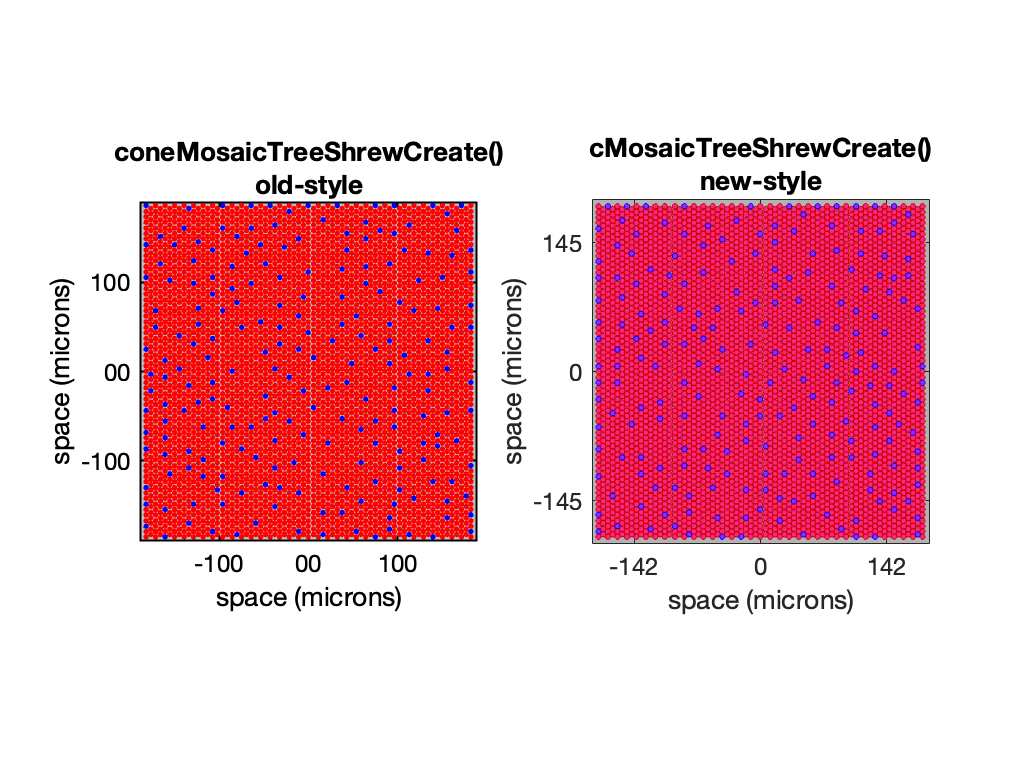

% Display the old and the new cone mosaics side-by-side
hFig = figure(1);
ax = subplot(1,2,1);
theOldStyleTreeShrewConeMosaic.visualizeGrid(...
    'axesHandle', ax, ...
    'ticksInMicrons', true, ...
    'visualizedConeAperture',  'lightCollectingArea', ...
    'plotTitle', sprintf('coneMosaicTreeShrewCreate()\nold-style'));
set(ax,'fontSize', 12);
  

ax = subplot(1,2,2);
theNewStyleTreeShrewConeMosaic.visualize(...
    'figureHandle', hFig, ...
    'axesHandle', ax, ...
    'domain', 'microns', ...
    'visualizedConeAperture',  'lightCollectingArea', ...
    'plotTitle', sprintf('cMosaicTreeShrewCreate()\nnew-style'), ...
    'fontSize', 12);

# **Step 4.** Compute the stimulus (a sinusoidal grating generated on a display) and its optical image

% Create presentation display and place it 5 cm in front of the eye
presentationDisplay = displayCreate(...
    'LCD-Apple', 'viewing distance', 5/100);

% Parameter struct for a sinusoidal grating stimulus 
stimParams = struct(...
    'spatialFrequencyCyclesPerDeg', 1.0, ... % 3.0 cycles/deg
    'orientationDegs', 0, ...               % 0 degrees
    'phaseDegs', 0, ...                     % spatial phase degrees, 0 = cos, 90 = sin
    'sizeDegs', sceneFOVdegs, ...           % size in degrees
    'sigmaDegs', 1, ...                     % sigma of Gaussian envelope
    'contrast', 0.9,...                     % 0.9 Michelson contrast
    'meanLuminanceCdPerM2', 40, ...         % 40 cd/m2 mean luminance
    'pixelsAlongWidthDim', [], ...          % pixels- width dimension
    'pixelsAlongHeightDim', [] ...          % pixel- height dimension
    );

% Generate a scene representing the Gabor stimulus with the above params as
% realized on the presentationDisplay
realizedStimulusScene = generateGaborScene(...
    'stimParams', stimParams,...
    'presentationDisplay', presentationDisplay, ...
    'minimumPixelsPerHalfPeriod', 5);

% Compute the optical image under TreeShrew optics
theOI = oiCompute(realizedStimulusScene, theOI);


# **Step 5.** Compute 256 response instances with the old- and the new-style cone mosaics

% Generate 256 response instances
nTrialsNum = 256;
emPath = zeros(nTrialsNum, 1, 2);

% Compute and time the only-style (@coneMosaicHex) cone mosaic activation
t1 = clock();
theConeMosaicHexActivationInstances = ...
    theOldStyleTreeShrewConeMosaic.compute(...
        theOI, 'emPath', emPath); 
t2 = clock();
oldStyleComputeTime = etime(t2,t1);

% Compute and time the new-style (@cMosaic) cone mosaic activation
t1 = clock();
[~,theCMosaicActivationInstances] = ...
    theNewStyleTreeShrewConeMosaic.compute(...
        theOI, 'nTrials', nTrialsNum); 

	Skipping blur by cone aperture.
	Consider increasing the # of pixels in the stimulus or decrease the stimulus FOV.


t2 = clock();
newStyleComputeTime = etime(t2,t1);

# **Step 6.** Contrast the performance of the new- vs. the old-style cone mosaics

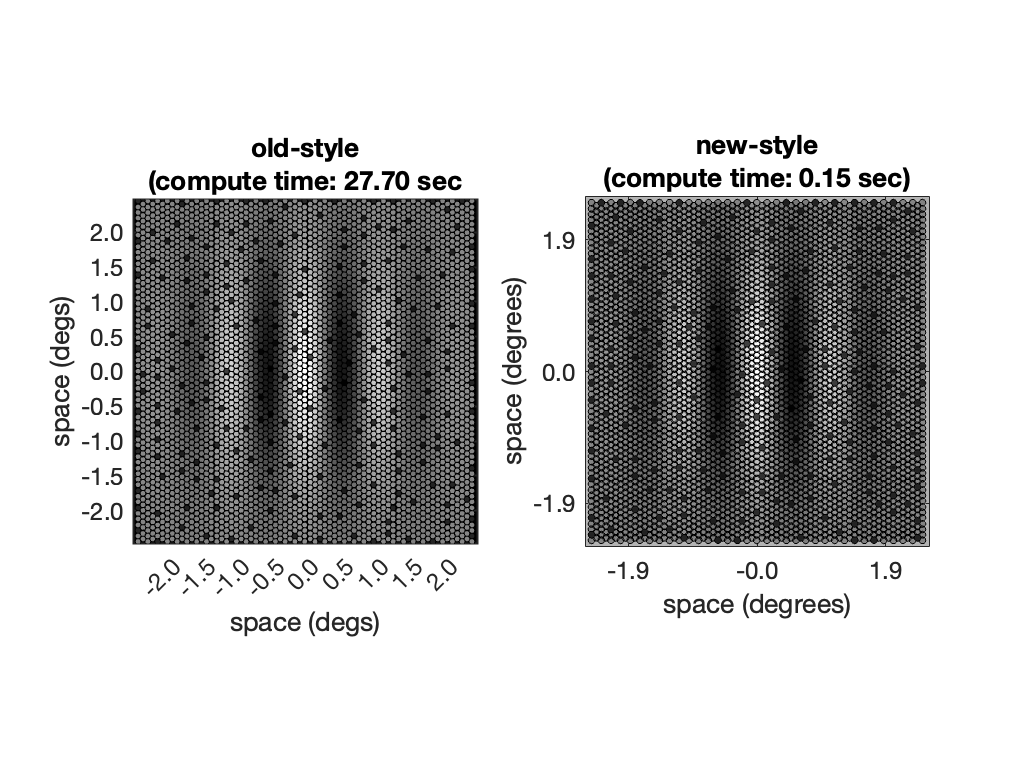

% Plot the spatial pattern of cone mosaic responses
hFig = figure(2); clf;
meanConeMosaicHexActivation = squeeze(mean(theConeMosaicHexActivationInstances,1));
meanCMosaicActivation = squeeze(mean(theCMosaicActivationInstances,1));

% The old-style cone mosaic responses
ax = subplot(1,2,1);
theOldStyleTreeShrewConeMosaic.renderActivationMap(ax, ...
    meanConeMosaicHexActivation, ...
    'mapType', 'modulated disks');
title(ax, sprintf('old-style\n(compute time: %2.2f sec', oldStyleComputeTime));
set(ax, 'FontSize', 12);

% The new-style cone mosaic responses
ax = subplot(1,2,2);
theNewStyleTreeShrewConeMosaic.visualize(...
    'figureHandle', hFig, ...
    'axesHandle', ax, ...
    'activation', meanCMosaicActivation, ...
    'plotTitle', sprintf('new-style\n(compute time: %2.2f sec)', newStyleComputeTime), ...
    'fontSize', 12);

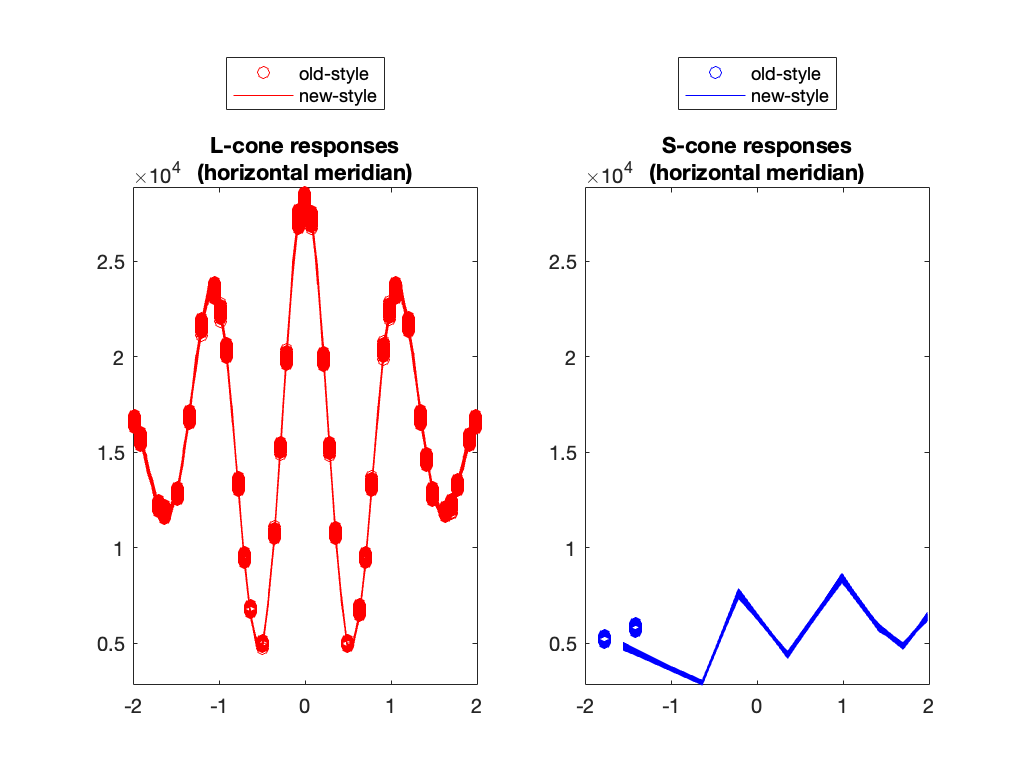


% Retrieve indices of all-cones along the horizontal meridian-old style mosaic
targetPosDegs(:,1) = -2:0.1:2;
targetPosDegs(:,2) = 0.*targetPosDegs(:,1) + 0.2;
[coneIndices, conePositions, coneTypes] = ...
            theOldStyleTreeShrewConeMosaic.indicesForConesAtPositions(targetPosDegs);

% Retrieve indices of L-cones along the horizontal meridian
idx = find(coneTypes == 2);
lConeIndices = coneIndices(idx);
lConeXPositionsOldStyle  = conePositions(idx,1);
lConeYPositionsOldStyle  = conePositions(idx,2);


% Retrieve indices of S-cones along the horizontal meridian
idx = find(coneTypes == 4);
sConeIndices = coneIndices(idx);
sConeXPositionsOldStyle = conePositions(idx,1);
sConeYPositionsOldStyle = conePositions(idx,2);

% Assemble positions and responses of L-cones along the horizontal meridian
lConeResponsesOldStyle = zeros(nTrialsNum, numel(lConeXPositionsOldStyle));
sConeResponsesOldStyle = zeros(nTrialsNum, numel(sConeXPositionsOldStyle));
for i = 1:nTrialsNum
    theActivation = squeeze(theConeMosaicHexActivationInstances(i,:,:));
    lConeResponsesOldStyle(i,:) = theActivation(lConeIndices);
    sConeResponsesOldStyle(i,:) = theActivation(sConeIndices);
end

% Extract cone responses along the horizontal meridian for the new-style mosaic
theLineROI = regionOfInterest('shape', 'line', 'from', [-2 0], 'to', [2 0], 'thickness', 0.2);
coneIndicesAlongHorizontalMeridian = theLineROI.indicesOfPointsInside(theNewStyleTreeShrewConeMosaic.coneRFpositionsDegs);
idx = find(theNewStyleTreeShrewConeMosaic.coneTypes(coneIndicesAlongHorizontalMeridian) == cMosaic.LCONE_ID);
lConeIndices = coneIndicesAlongHorizontalMeridian(idx);
lConeXPositionsNewStyle = theNewStyleTreeShrewConeMosaic.coneRFpositionsDegs(lConeIndices,1);
lConeResponsesNewStyle = squeeze(theCMosaicActivationInstances(:, 1, lConeIndices));

idx = find(theNewStyleTreeShrewConeMosaic.coneTypes(coneIndicesAlongHorizontalMeridian) == cMosaic.SCONE_ID);
sConeIndices = coneIndicesAlongHorizontalMeridian(idx);
sConeXPositionsNewStyle = theNewStyleTreeShrewConeMosaic.coneRFpositionsDegs(sConeIndices,1);
sConeResponsesNewStyle = squeeze(theCMosaicActivationInstances(:, 1, sConeIndices));



hFig = figure(4);clf;
ax = subplot(1,2,1);
% The old-style cone mosaic responses
p1 = plot(ax,lConeXPositionsOldStyle, lConeResponsesOldStyle, 'ro');
hold(ax, 'on');
p2 = plot(ax,lConeXPositionsNewStyle, lConeResponsesNewStyle, 'r-');
set(ax, 'YLim', [min(sConeResponsesNewStyle(:)) max(lConeResponsesNewStyle(:))]);
legend([p1(1) p2(1)], {'old-style', 'new-style'}, 'Location', 'NorthOutside')
title(sprintf('L-cone responses\n(horizontal meridian)'))

ax = subplot(1,2,2);
p1 = plot(ax,sConeXPositionsOldStyle, sConeResponsesOldStyle, 'bo');
hold(ax, 'on');
p2 = plot(ax,sConeXPositionsNewStyle, sConeResponsesNewStyle, 'b-');
set(ax, 'YLim', [min(sConeResponsesNewStyle(:)) max(lConeResponsesNewStyle(:))]);
legend([p1(1) p2(1)], {'old-style', 'new-style'}, 'Location', 'NorthOutside')
title(sprintf('S-cone responses\n(horizontal meridian)'));